# ENGR105    ---    Problem Set 6    ---   Logicals and functions

## Due: Friday, 10/16/2020

## Name:

#### The University of Pennsylvania code of academic integrity can be found here:

[https://catalog.upenn.edu/pennbook/code-of-academic-integrity/](https://catalog.upenn.edu/pennbook/code-of-academic-integrity/)

By submitting this assignment, you certify that you completed this assignment in compliance with the code of academic integrity, as defined above, and that the work here is your own. Collaboration is allowed and encouraged but  it is in your own best interest to be able to complete all the problems on your own. Collaboration is allowed, COPYING is NOT. Be sure you are able to reason through each step. 

#### Notes on HW submission:

- Please save the final document In the following format: "<your last name>_<your first name>_HW6.mlx

- Run the entire document (`f5`) prior to submitting. Following this, please **export to .pdf** and **submit both** the .mlx file and the .pdf file to Canvas.

- The LiveScript file may be exported to PDF using the **Save** dropdown menu. **Please also see my recent email regarding alternative methods for exporting to PDF.**

- If it is not selected by default, select "Output Inline" at the top right of the LiveScript document to display the output below your code (rather than to the right).

#### Purpose of this problem set:

- Gain familiarity with logical statements and arrays.

- Practice applying course material to solve an engineering problem.

- Develop familiarity with function handles.

- Develop rules for a gameplay algorithm and directly observe how those play out in a familiar setting.

#### Notes about MATLAB LiveScripts:

- The gray regions are "code" regions. Entering and running your code here is the same as running it in a `.m` script file or on the command line.

- "Running a piece of code" means you are executing the code in that section only. **Press **`Cntl`** + **`Enter`** to run a given section.**

- Press `f5` to run all sections of the document.

- To remove inline figures, right click and select "Clear All Output."

- When you run a section (each section refers to a different problem or part of a problem), all variables and vectors are stored in MATLAB and may be called from the command line.

**Reminder: Prior to submitting, be sure to run ****all**** sections of the document to ensure that it works properly. After running all sections, export the document to pdf.**

## PROBLEM 1 (10 pts): Catch your breath

During week 6, I want you to take some time to "catch your breath" and regroup in ENGR 105. You should:

- Complete and submit any assignments you have not yet submitted.

- Look through prior homeworks and lecture material for topics and areas that you feel unsure about. Ask the me, the TAs, or your classmates about these topics.

- Do some optional practice problems (if you want more practice) -- this is completely optional and you should only do these if you want more practice.

- Make 30 minutes to do something that makes you happy.

**a)** **(5 pts) Complete and submit any prior unsubmitted homework assignments**. If you do not have any unsubmitted homework assignments when you submit HW6, you will automatically receive these five points.

**b)** **(5 pts) In the space provided here, write** (no more than four sentences) about something that you have done or experienced recently that **made you smile **or** feel happy**. 

***Your response:***

One thing that has made me happy was going to look at houses with my family. We have lived in the same apartment since I was born, so it was nice seeing my mom happy and ready to move again. Also, looking at houses is pretty satisfying as well. 

## PROBLEM 2 (15 pts): Logical arrays

Consider arrays$A$ and $B$, defined here.

            
$$A=\left\lbrack \begin{array}{ccc}
11 & 14 & 17\\
12 & 15 & 18\\
13 & 16 & 19
\end{array}\right\rbrack$$


            
$$B=\left\lbrack \begin{array}{ccc}
0 & 1 & 2\\
0 & 1 & 2\\
0 & 1 & 2
\end{array}\right\rbrack$$


A = reshape(11:19,3,3); % Define matrix A
B = ones(3,1)*(0:2);    % Define matrix B

Using $A$, $B$, and **only**** logical indexing, array math, **and the **array restructuring functions covered in lecture, **produce each of the following arrays in one line of code. Acceptable restructuring functions for this problem are: `rot90()`, `flipud()`, and `fliplr()`. **Do not use** array/vector indexing, array concatenation, explicitly defined elements, the transpose function, or any other array functions. For each part, please do not supress your code to ensure that each array that is output is visible.

**a) **$\textrm{p2}\_a=\left\lbrack \begin{array}{ccc}
11 & 14 & 17\\
12 & 0 & 18\\
13 & 16 & 19
\end{array}\right\rbrack$

p2_a = (A ~= 15) .* A

p2_a =     11    14    17
    12     0    18
    13    16    19


**b) **$\textrm{p2}\_b=\left\lbrack \begin{array}{ccc}
14 & 15 & 16
\end{array}\right\rbrack$

 p2_b = rot90(A(A == 14 | A == 15 | A == 16))

p2_b =     14    15    16


**c) **$\textrm{p2}\_c=\left\lbrack \begin{array}{ccc}
0 & 1 & 2
\end{array}\right\rbrack$

 p2_c = rot90(B(A == 11:3:17))

p2_c =      0     1     2


**d) **$\textrm{p2}\_d=\left\lbrack \begin{array}{ccc}
11 & 0 & 17\\
0 & 15 & 0\\
13 & 0 & 19
\end{array}\right\rbrack$

p2_d = (mod(A,2) ~= 0).*A

p2_d =     11     0    17
     0    15     0
    13     0    19


**e) **$\textrm{p2}\_e=\left\lbrack \begin{array}{ccc}
22 & 0 & 0\\
12 & 0 & 0\\
0 & 0 & 0
\end{array}\right\rbrack$

p2_e = rot90(B).*(A == 11 | A == 12).*A

p2_e =     22     0     0
    12     0     0
     0     0     0


## PROBLEM 3 (25 pts): Batch chemical reactor

A classic topic in chemical engineering is **reactor design**, in which the engineer uses her or his knowledge of chemical kinetics, thermodynamics, heat transfer, mass transfer, and fluid mechanics to design reaction units to convert reactants into the desired products. One type of reactor is known as a **batch reactor**, in which the precursor material is initially present in the reactor, there are no fluidic inputs or outputs, and the chemical reaction is able to proceed until the system is stopped by the engineer.

Consider a batch reactor in which the **concentration of chemical species A** as a function of time is described by the following equation.

            
$$C_A \left(t\right)=5e^{-\left(k\;t\;+\;e^{-t} -1\right)}$$


In this equation, $C_A \left(t\right)$ (units of molarity) is the concentration profile of species $A$ as a function of time, and $k$ is the first order rate constant (with units of $1/\textrm{minutes}$) describing the degradation of species $A$. Assume all units in the above equation agree.

**a)** **Plot the concentration** of species $A$ for $0\le t\le 10\;\textrm{minutes}$, for $k=0\ldotp 5,\;k=1,\;k=5$. Plot all three curves on the same plot. Be sure to include a legend, axis labels, and title. 

% Plot t vector
t = 0:0.1:10;
% Define function handle
C = @(k) 5*exp(-((k*t)+exp(-t)-1))

C = function_handle with value:
    @(k)5*exp(-((k*t)+exp(-t)-1))


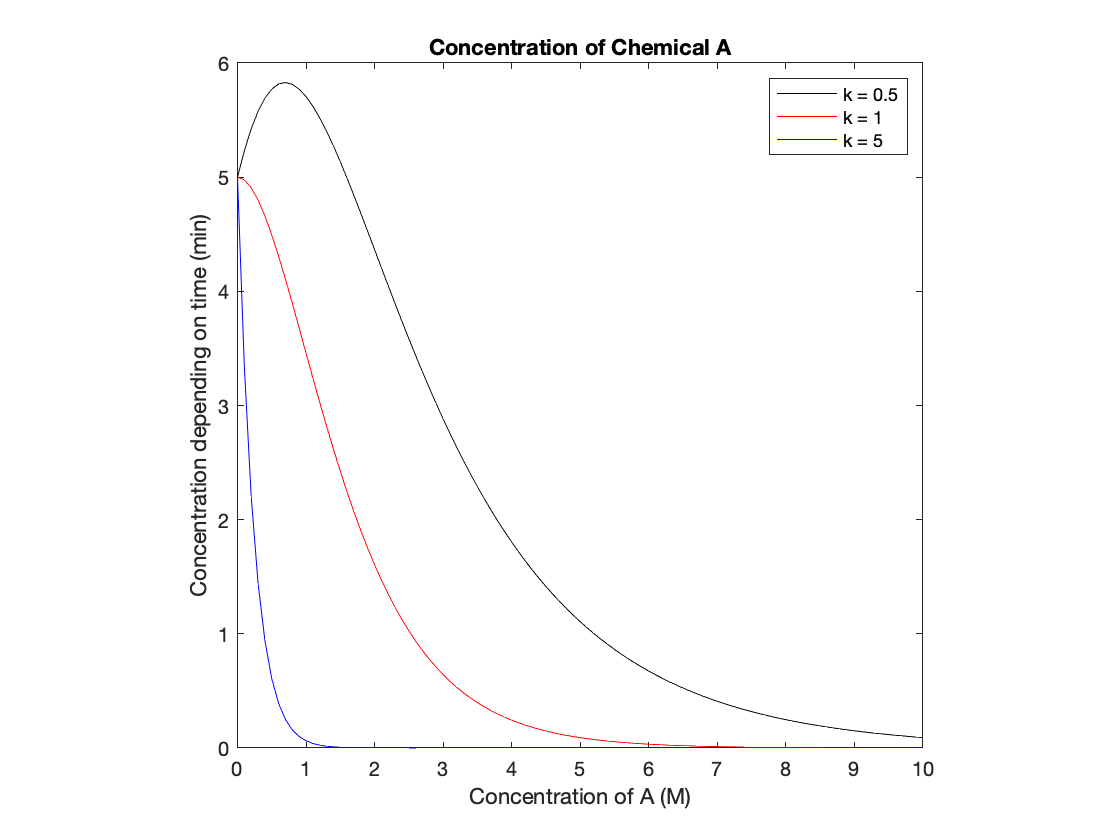


% Plot function for each k
plot(t,C(0.5),'k-')
hold on     % plot on the same set of axis
plot(t,C(1),'r-')
hold on     % plot on the same set of axis
plot(t,C(5),'b-')
hold off    % turn "off" plotting on the same set of axis

axis square
legend('k = 0.5','k = 1', 'k = 5')
xlabel('Concentration of A (M)')
ylabel('Concentration depending on time (min)')
title('Concentration of Chemical A')

**b)** In this system, assume you are interested in the **time required for 95% of species **$A$** to be ****converted**** into products**.** Call this time **$t_{95}$. Further assume that the rate constant $k$ is tunable (*i.e.* we can potentially vary $k$ experimentally) by changing the reactor temperature or introducing a catalyst. Plot $t_{95}$ vs. $k$ for $k$ values between 0.5 and 50;

t_95 = [];
%incrament t until t is within the 5 percent 
for k =0.5:1:50 
    t = 0;
    %function that finds the concentration depending on the k value
    C = @(k)5*exp(-(k*t+exp(-t)-1));
    %concentration at the initial time 
    Cint = 5*exp(-(k*0+exp(-0)-1));
    %if the conditon is fufiled, increase t slightly for the values that
    %work
    while C(k) - 0.05*Cint > 10^-6
        %incrament slighly
        t = t + 0.0001;
        C = @(k)5*exp(-(k*t+exp(-t)-1));
    end
    %need to add t to the end
    t_95(end+1) = t;
end
disp(length(t_95))

    50



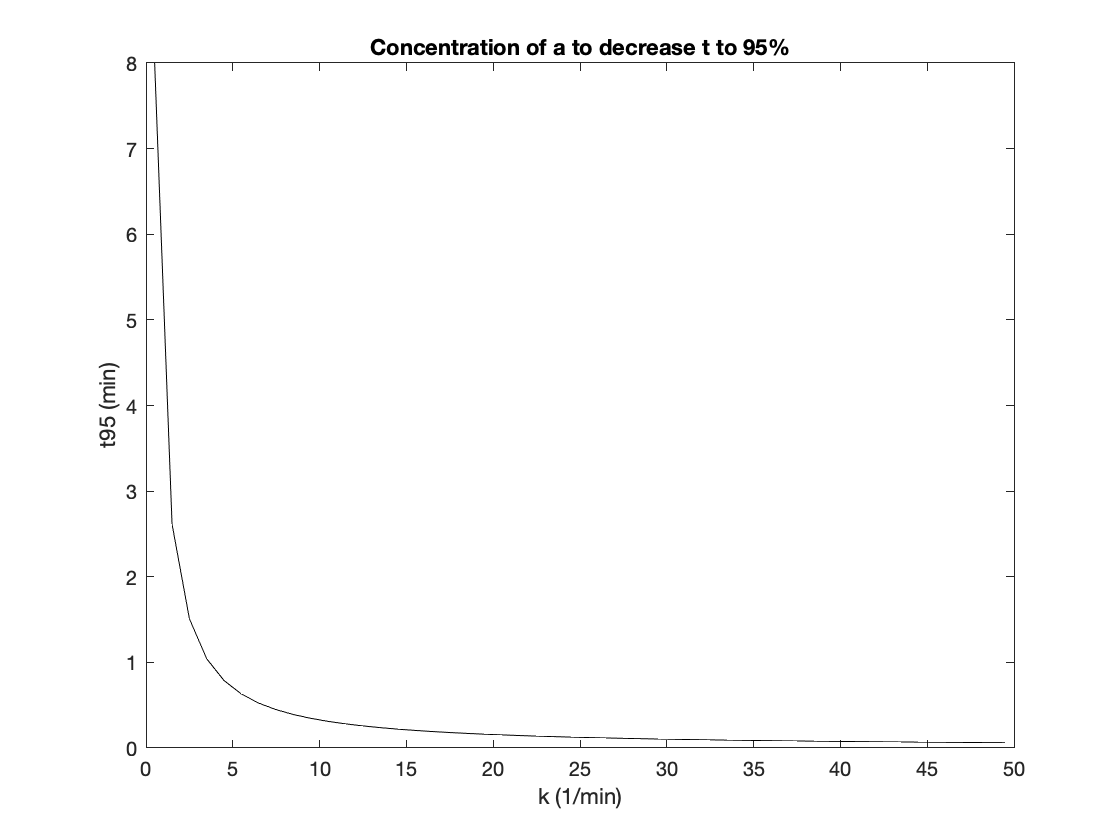

k = 0.5:1:50;
plot(k,t_95,'k-')
xlabel('k (1/min)')
ylabel('t95 (min)')
title('Concentration of a to decrease t to 95%')

## PROBLEM 4 (15 pts): Function handles

A function handle is a MATLAB data type that stores an **association to a function**. We use the `@` symbol in front of a function name to create a function handle. Note that the function handle is stored in a separate variable. Function handles are useful in a few different circumstances. For our purposes, we are especially interested in using them to "**pass one function into another function**," which will be useful as we continue to use differential equation solvers and other numerical methods.

Consider the **matrix **$A$, below, and the **functions p4_fxn1**`()`**, p4_fxn2**`()`**, and p4_fxn3**`()` created at the end of this LiveScript document. In this problem, you will use function handles to create new matrices.

        
$$A=\left\lbrack \begin{array}{cc}
1 & 3\\
2 & 4
\end{array}\right\rbrack$$


A = reshape(1:4,2,2)

A =      1     3
     2     4


**a)** **Create function handles** for p4_fxn1`()`, p4_fxn2`()`, and p4_fxn3`()`.

f1 = @p4_fxn1;
f2 = @p4_fxn2;
f3 = @p4_fxn3;



**b)** **Using ****only**** the function handles** and $A$, **create each of the following matrices** using one line of code.

*i)* $\textrm{p4}\_i=\left\lbrack \begin{array}{cc}
2 & 4\\
3 & 5
\end{array}\right\rbrack$

p4_i = f1(A)

*ii)* $\textrm{p4}\_\textrm{ii}=\left\lbrack \begin{array}{cc}
1 & 9\\
4 & 16
\end{array}\right\rbrack$

p4_ii = f2(A)

*iii)* $\textrm{p4}\_\textrm{iii}=\left\lbrack \begin{array}{cc}
4 & 16\\
9 & 25
\end{array}\right\rbrack$

p4_iii = f2(f1(A))

p4_iii =      4    16
     9    25


*iv) *$\textrm{p4}\_\textrm{iv}=\left\lbrack \begin{array}{cc}
0 & 0\\
4 & 0
\end{array}\right\rbrack$

p4_iv = f3(f2,A)

p4_iv =      0     0
     4     0


*v)* $\textrm{p4}\_v=\left\lbrack \begin{array}{cc}
4 & 0\\
0 & 0
\end{array}\right\rbrack$

p4_v = f3(f2, f1(A));

*vi)* $\textrm{p4}\_\textrm{vi}=\left\lbrack \begin{array}{cc}
1 & 1\\
1 & 1
\end{array}\right\rbrack$

%p4_vi = f1(A) - A
p4_vi = f1(f3(f1, f2(A)))

p4_vi =      1     1
     1     1


## PROBLEM 5 (35 pts): Tic tac toe

In class, we created a MATLAB script for playing Tic Tac Toe against the computer. We started by considering a simpler problem describing two player Tic Tac Toe and then built up our code such that we were playing against a computer player who chose its next move randomly based on the available positions. In this problem, you will generalize this code so that we can easily change the computer player's strategy. That is, we will update our code to include function handles.

**a) **Convert the MATLAB script that we made in class into a **function** named `ticTacToe`, and store this function in the space provided at the end of this LiveScript document. `ticTacToe` should take **another function** that specifies *how* the computer should play as its **one input**. 

- Additionally, create a function in this LiveScript document called `randomPlayer`. This function should be the same as what we created in class.

**Call **`ticTacToe(@randomPlayer)`** here** to ensure that it works as expected. Please leave the output from a typical game displayed when you convert this document to PDF.

% Play tic tac toe against AI player who plays randomly

ticTacToe(@randomPlayer)

     1     0     0
     0     0     0
     0     0     0

     1     0     0
     0     0     2
     0     0     0

     1     0     0
     1     0     2
     0     0     0

     1     0     2
     1     0     2
     0     0     0

     1     0     2
     1     0     2
     1     0     0

1wins!


**This code should work exactly as it did in class.** The only difference is that now we have the code in a convenient format for easily changing the computer's strategy.* Please feel free to modify our tic tac toe script from class in whatever ways you feel makes it more optimal, easier to understand, or clearer*. For the rest of this problem, you should **NOT** modify the function `ticTacToe()`.

**b)**  Create a new function called `playerBad()` in the space provided at the end of this LiveScript document. This function should create a computational strategy that is **bad** at playing Tic Tac Toe and should take whatever necessary inputs to run properly. As above, the computer player should always be Player 2.

**Call **`ticTacToe(@playerBad)`** here** to ensure that it works as expected. Please leave the output from a typical game displayed when you convert this document to PDF.

% Play tic tac toe against AI player who plays "poorly"
ticTacToe(@badPlayer)

     1     0     0
     0     0     0
     0     0     0

     1     0     0
     0     0     0
     0     0     2

     1     0     0
     1     0     0
     0     0     2

     1     0     0
     1     0     2
     0     0     2

     1     0     0
     1     0     2
     1     0     2

1wins!


Additionally, **explain (concisely) how your "bad" tic tac toe strategy works** and** why you chose it**.

***Your response:***

This code is bad because it avoids taking the middle which is the ideal spot to start out with. Afterwards, it just fills in from the highest valued positiion, so as long as the player starts at the low value, they would never meet the computer.

**c) **Create a new function called `playerGood()` in the space provided at the end of this LiveScript document. This function should create a computational strategy that is **good** at playing Tic Tac Toe and should take whatever necessary inputs to run properly. As above, the computer player should always be Player 2.

**Call **`ticTacToe(@playerGood)`** here** to ensure that it works as expected. Please leave the output from a typical game displayed when you convert this document to PDF. 

% Play tic tac toe against AI player who plays "well"
ticTacToe(@goodPlayer)

     1     0     0
     0     0     0
     0     0     0

     1     0     0
     0     2     0
     0     0     0

     1     0     0
     1     2     0
     0     0     0

     1     0     0
     1     2     0
     2     0     0

     1     0     1
     1     2     0
     2     0     0

     1     2     1
     1     2     0
     2     0     0

     1     2     1
     1     2     0
     2     1     0

     1     2     1
     1     2     2
     2     1     0

     1     2     1
     1     2     2
     2     1     1

Draw!


Additionally, **explain (concisely) how your "good" tic tac toe strategy works** and **why you chose it**.

***Your response:***

For this code, I was aiming to check for when the player is close to a winning condition, and if so the computer would play in the empty space that is not taken by the player. 

## Problem Set 6: functions stored below

**This space contains the three functions to be used for PROBLEM 3, if necessary.**

**This space contains the three functions to be used for PROBLEM 4**

function output1 = p4_fxn1(input1)
    % This is the first function in Problem 4
    output1 = input1 + 1;

end

function output2 = p4_fxn2(input2)
    % This is the second function in Problem 4
    output2 = input2.^2;

end

function output3 = p4_fxn3(fxn3,input3)
    % This is the third function in Problem 4
    output3 = fxn3(input3).*(input3 == 2);

end

**Use the space below for PROBLEM 5, a).**

function ticTacToe(playerStrategy)
    % NOTE: this is the updated code that we made up to and including 10/6.
    
    % Define initial variables and arrays
    gameboard = zeros(3,3); % gameboard that we will populate
    
    % Repeat: alternate for players
    player = 1; % player one
    
    % Logical variable to determine if game should stil be playing
    gameStillGoing = 1;
    
    % Iterate until someone has won (or the game is a draw)
    while gameStillGoing
    
        % Player 1: human player. If it is player 1's turn, specify a
        % position to be played
        if player == 1
        
            % Logical variable corresponding if the move is valid
            invalidMove = 1;
            
            % Make player pick a valid position
            while invalidMove
            
                % Position to play, in single index notation
                playPos = input('Select a position to play...');
        
                % Determine if move is allowable
                invalidMove = all((gameboard(:) == 0)'.*(1:9) ~= playPos);
        
            end
        
        % Player 2: computer player. If it is player 2's turn, determine the
        % position played based on the algorithm contained within compStrategy().
        else
            % Call a function that will output a position based upon the
            % strategy defined for the computer
            playPos = playerStrategy(gameboard);
        end
        
        % Update the gameboard
        gameboard(playPos) = player;
        
        % Step 3: display game board
        disp(gameboard)
        
        % Step 4: evaluate stopping condition -> did someone win?
        gameStillGoing = checkEndGame2(gameboard, player);
        
        % Step 5: change player
        player = mod(player,2)+1;
    end
end

function out = checkEndGame2(gameboard, player)
    % Purpose: create a better function to evaluate if the game ends

    % by default, game is still going
    out = 1;
    
    % Array in whcih each row corresponds to a potential winning condition
    winCond = [gameboard;gameboard';diag(gameboard)';diag(rot90(gameboard))'];

    % Check to see if player wins
    if any(all(winCond == player,2))
        disp(strcat(num2str(player),'wins!'))
        out = 0;
        
    % End the game if it is a draw
    elseif isempty(gameboard(gameboard == 0))
        disp('Draw!')
        out = 0;
        
    end

end

function posPlayed = randomPlayer(gameboard)
    % This function contains code describing the computer player's strategy

    availablePos = (gameboard(:) == 0)'.*(1:9);
    
    positions = availablePos(availablePos > 0);
    
    % Return a random (available) position. This code thus has the computer
    % play randomly based upon the available positions
    posPlayed = positions(randi(length(positions)));


end


**Use the space below for PROBLEM 5,b).**


%try to check the rows and play not where the enemy is playing 
function out = badPlayer(gameboard)
%     gameboard_p1 = reshape(p1_moves,3,3);
%     blankGameBoard = reshape(1:9,3,3);
%     
%     %check where the player played and then play on the opposite side of
%     %the board 
%     
%     for m = 1:3
%         for n = 1:3
%             %checks where the player played
%             if gameboard_p1(m,n) == 1 
%                 %now want to play furthest away 
%                 posPlayed = gameboard
%             end
%         end
%     end

    availablePos = (gameboard(:) == 0)' .* (1:9);
    blankGameBoardPos = reshape(1:9,3,3);
    %posPlay = 1;
    %positions that can be played
    positions = availablePos(availablePos > 0);
   

  %check if the middle spot was taken b/c that seems like an ideal spot
    if length(positions) == 8
        if all(positions ~= 5)
            %if it was taken, play in one of the corners
            non_corners = positions((mod(positions,2) == 0));
            i = randi(length(non_corners));
            out = non_corners(i);
        else 
            out = 9;
        end 
    
    %just play from the higest number that is availale
    else 
        out = positions(end);
    end
 
end

    









**Use the space below for PROBLEM 5,c).**


% a good system for player 2 can be to block the per
function posPlay = goodPlayer(gameboard)
    %check what the position currently the player is currently in 
    %place a piece adjacent to where the player is 
    %check if two in the same row is equal to player 1 or 2
    % if 2 in a row is equal to player 1, place a 2 in the empty slot that
    % is not where player pne is 
    
    availablePos = (gameboard(:) == 0)' .* (1:9);
    blankGameBoardPos = reshape(1:9,3,3);
    
    %positions that can be played
    positions = availablePos(availablePos > 0);
    %prevPlayed = (gameboard(:) == 1)'.* (1:9);
    %rewrite winCondition so that it is when we are about to win.
    winCond = [gameboard;gameboard';diag(gameboard)';diag(rot90(gameboard))'];
    winCondPos = [blankGameBoardPos;blankGameBoardPos';diag(blankGameBoardPos)';diag(rot90(blankGameBoardPos))'];
    
    %check if the middle spot was taken b/c that seems like an ideal spot
    if length(positions) == 8
        if all(positions ~= 5)
            %if it was taken, play in one of the corners
            corners = positions((mod(positions,2) > 0));
            i = randi(length(corners));
            out = corners(i);
        else 
            out = 5; 
        end 
   
    %checking if we are close to a win condition
    elseif any((sum(winCond == 1,2) == 2) & sum(winCond,2) == 2)
        row = 1;
        while sum(winCond(row,:)) ~= 2
             row = row + 1;
        end
        if sum(winCond(row,:)) == 2
            
            %prints the position that is not filled but inversing the
            %positions that are filled.
            zeroColumn = (1:3)*(~winCond(row,:))';
        end
        out = winCondPos(row,zeroColumn);
    %next just play randmomly if the condition is nit met
    else
        out = positions(randi(length(positions)));
    end
    
   posPlay = out;
end








